clc
close all
clear all

## read image

raw_img = imread('FiveCarsParked.jpg');
raw_img = imresize(raw_img,[400 nan]);

## read empty parking space

empty_img = imread('NoCarParked.jpg');
empty_img = imresize(empty_img,[400 nan]);

## subtract to get rid of parking lines

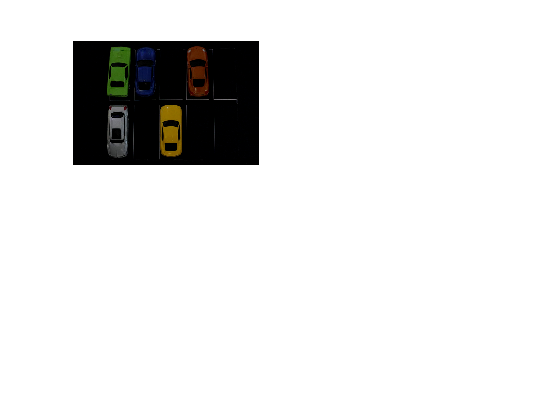

img = imsubtract(raw_img,empty_img);
subplot(2,2,1),imshow(img);

## convert from RGB to grayscale

igray = rgb2gray(img);

## convert from grayscale to binary with specified threshold

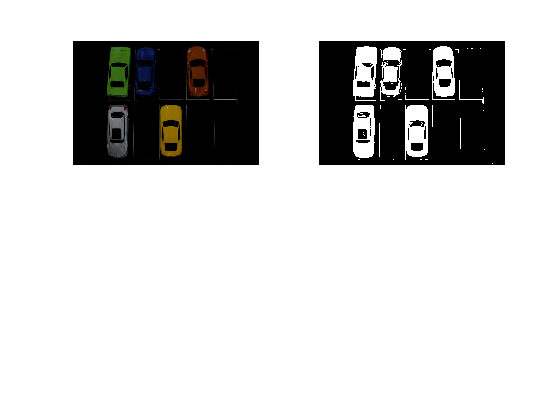

level = 0.02;
ithresh = im2bw(igray,level);
subplot(2,2,2), imshow(ithresh);

## fill holes

ifilled = imfill(ithresh,'holes');

## shaping every object with specified disk size

se = strel('disk',5);
iopen = imopen(ifilled,se);

## remove small unnecessary objects

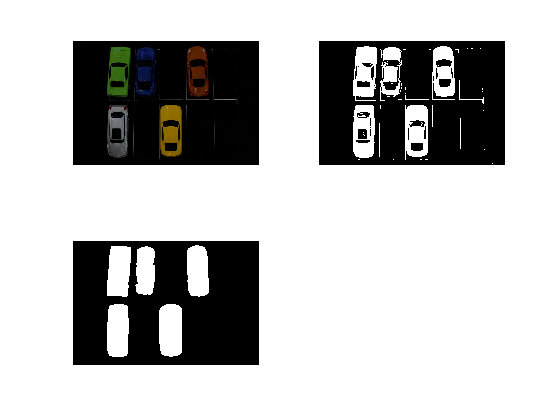

iclear = bwareaopen(iopen,4,4);
subplot(2,2,3), imshow(iclear);

## making boundary boxes around detected cars

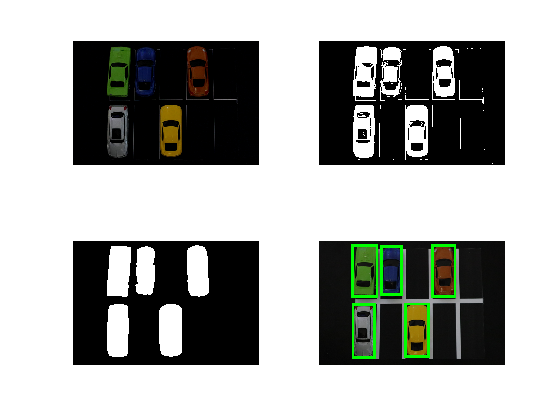

subplot(2,2,4),imshow(raw_img);
props = regionprops(iclear,'BoundingBox','Image');
for i=1:size(props,1)
rectangle('Position',props(i).BoundingBox,'EdgeColor','g','LineWidth',2);
end

## count no. of cars and print available spots

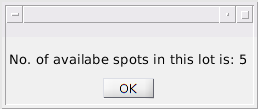

f = msgbox(['No. of availabe spots in this lot is: ',num2str(10-i)]);